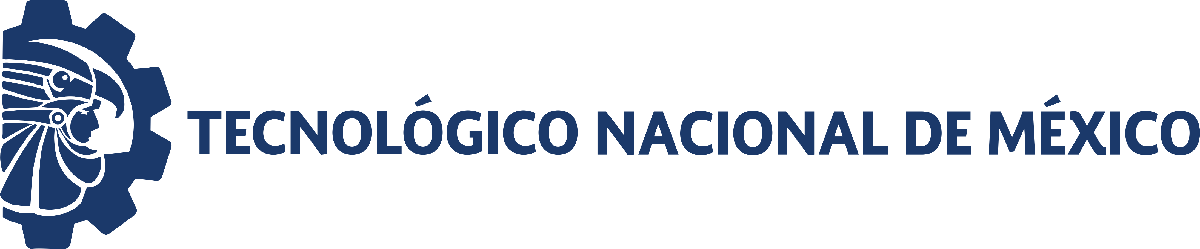                                 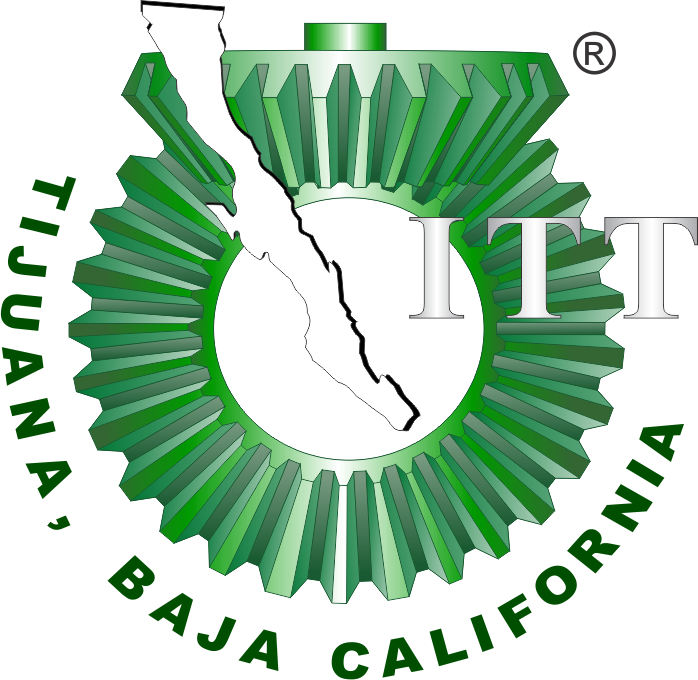

# Práctica 2: Sistema Presa Depredador

# **Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

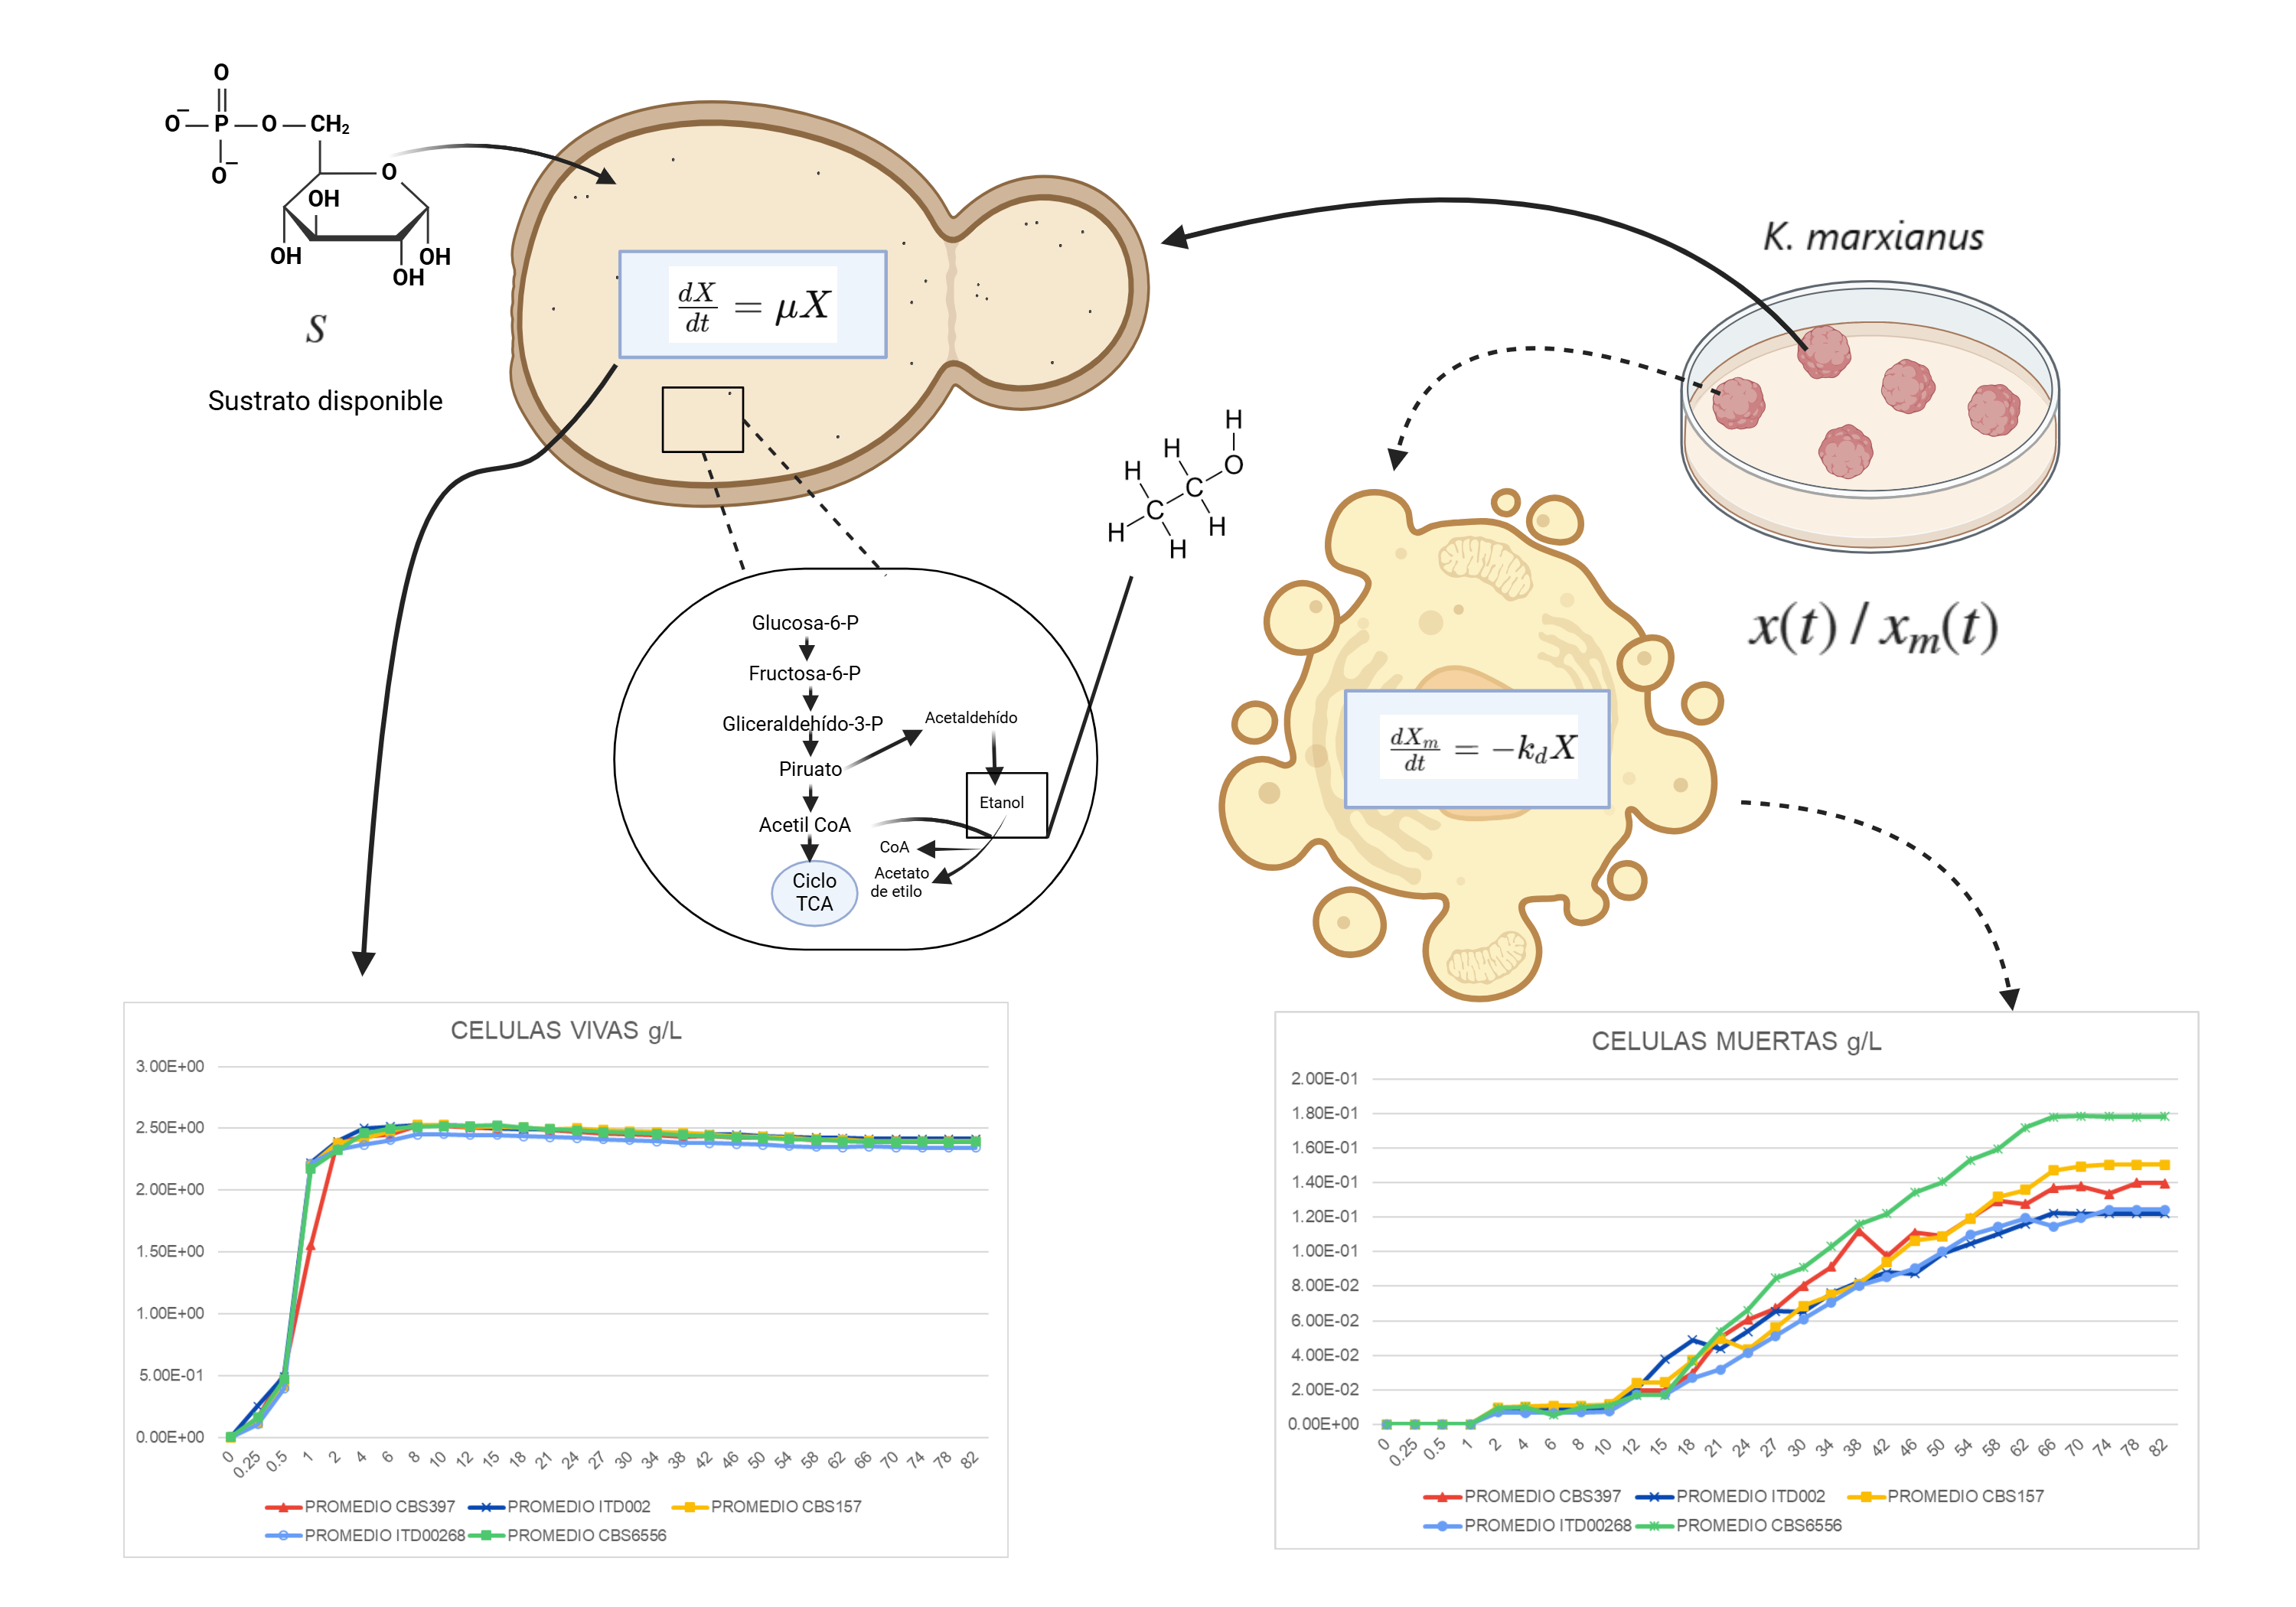

Nombre del alumno: **Mendivil Ramirez Frida Daniela **

Número de control: **20211983**

Correo institucional: **L20211983@tectijuana.edu.mx**

Carrera: **Ingeniería Biomédica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

### objetivo

Solucionar las ecuaciones de Lotka-Volterra para estudiar e ilustrar su dinamica en series de tiempo y el plano de fase. El sistema presa-depredador se formula mediante las siguientes dos EDOSs de primer orden:

$\overset{\ldotp }{x} =\alpha x-\beta \textrm{xy}$,          (8.1)

$\overset{\ldotp }{y} =\delta \textrm{xy}-\gamma y$,           (8.2)

con los valores de los parametros $\alpha =0\ldotp 5$, $\delta =0\ldotp 005$ y $\gamma =0\ldotp 2$, y las condiciones iniciales $x\left(0\right)=x_0 =75$ y $y\;\left(0\right)=y_0 =75$.

### Simulation data

clc; clear; close all; warning('off','all')

### Parameters an initial conditions

alpha = 0.5; beta = 0.01;
delta = 0.001; gamma = 0.2;
P = [alpha,beta,delta,gamma];
x0 = 75; y0 = 75; tend = 100;

### Solution by Euler method

%dt = [2,1,0.5,0.25,1E-1,1E-2,1E-3,1E-4];
dt = 1E-4;
for i = 1:numel(dt)
    [t,x,y] = sys_Euler(x0,y0,dt(i),tend,P);
    plotEDOs(t,x,y,P,dt(i))
    exportgraphics(gcf,['Lotka-Volterra Euler',num2str(dt(i)),'.pdf'], 'ContentType', 'Vector')
end

### Simulink

file = 'Frida';
sim(file);
parameters.StopTime = '100';

#### Solution by ode15s [Stiff solver]

parameters.Solver = 'ode15s';
s15s = sim(file,parameters);
plotEDOs(s15s.t,s15s.x,s15s.y,P,0)
    exportgraphics(gcf,['Lotka-Volterra ode15s.pdf'], 'ContentType', 'Vector')

#### Solution by ode23s [Stiff solver]

parameters.Solver = 'ode23s';
s23s = sim(file,parameters);
plotEDOs(s23s.t,s23s.x,s23s.y,P,0)
    exportgraphics(gcf,['Lotka-Volterra ode23s.pdf'], 'ContentType', 'Vector')

#### Solution by ode23t [Stiff solver]

parameters.Solver = 'ode23t';
s23t = sim(file,parameters);
plotEDOs(s23t.t,s23t.x,s23t.y,P,0)
    exportgraphics(gcf,['Lotka-Volterra ode23t.pdf'], 'ContentType', 'Vector')

#### Solution by ode23tb [Stiff solver]

parameters.Solver = 'ode23tb';
s23tb = sim(file,parameters);
plotEDOs(s23tb.t,s23tb.x,s23tb.y,P,0)
    exportgraphics(gcf,['Lotka-Volterra ode23tb.pdf'], 'ContentType', 'Vector')

#### Solution by ode45 [Non Stiff solver]

parameters.Solver = 'ode45';
s45 = sim(file,parameters);
plotEDOs(s45.t,s45.x,s45.y,P,0)
    exportgraphics(gcf,['Lotka-Volterra ode45.pdf'], 'ContentType', 'Vector')

#### Solution by ode23 [Non Stiff solver]

parameters.Solver = 'ode23';
s23 = sim(file,parameters);
plotEDOs(s23.t,s23.x,s23.y,P,0)
    exportgraphics(gcf,['Lotka-Volterra ode23.pdf'], 'ContentType', 'Vector')

#### Solution by ode113 [Non Stiff solver]

parameters.Solver = 'ode113';
s113 = sim(file,parameters);
plotEDOs(s113.t,s113.x,s113.y,P,0)
    exportgraphics(gcf,['Lotka-Volterra ode113.pdf'], 'ContentType', 'Vector')

Con base en las simulaciones númericas y a que un sistema se considera stiff si el método numérico empleado, que posee una región finita de estabilidad absoluta, debe utilizar una longitud de paso que es desproporcionadamente pequeña en comparación con la suavidad de la solución exacta en el intervalo, se concluye que el sistema Lotka-Volterra es nonstiff.

Referencia. Talukdar, A. R. (2024). COMPARING RUNGE-KUTTA METHODS WITH LOTKA-VOLTERRA MODEL.

### Equilibrium points and Jacobian matrix

clear; close all; clc
syms x y alpha beta delta gamma
dx = alpha*x - beta*x*y;
dy = delta*x*y - gamma*y;
J = jacobian([dx,dy],[x,y]);
fprintf('Jacobian matrix of the Lotka-Volterra system:'); disp(J)

Jacobian matrix of the Lotka-Volterra system:

$$\left(\begin{array}{cc} \alpha -\beta \,y & -\beta \,x\\ \delta \,y & \delta \,x-\gamma \end{array}\right)$$

dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
edos = solve([dx,dy],[x,y]);
fprintf(['The Lotka-Volterra system has', num2str(length(edos.x)),'equilibrium points.'])

The Lotka-Volterra system has2equilibrium points.

X0 = edos.x(1); Y0=edos.y(1)

$$Y0 = 0$$

X1 = edos.x(2); Y1=edos.y(2)

$$Y1 = \frac{\alpha }{\beta }$$

syms x0 y0 x1 y1
fprintf('equilibrium points of the Lotka-Volterra systems:'),...
    disp([x0,y0,X0,Y0]); disp([x1,y1,X1,Y1])

equilibrium points of the Lotka-Volterra systems:

$$\left(\begin{array}{cccc} x_{0} & y_{0} & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{1} & y_{1} & \frac{\gamma }{\delta } & \frac{\alpha }{\beta } \end{array}\right)$$

clear alpha beta delta gamma
alpha = 0.5; beta = 0.01;
delta= 0.001; gamma= 0.2;
disp('(x0,y0)= (0,0)');...
    disp(['(x1,y1)=(', num2str(gamma/delta),',', num2str(alpha/beta),')'])

(x0,y0)= (0,0)


(x1,y1)=(200,50)


### Local stability

clc; clear; 
alpha = 0.5; beta = 0.01;
delta= 0.001; gamma= 0.2;
syms x y
dx= alpha*x - beta*x*y == 0;
dy= delta*x*y - gamma*y == 0;
edos= solve ([dx,dy], [x,y]);
x0 = double( edos.x(1)); y0 = double(edos.y(1));
x1 = double(edos.x(2)); y1 = double(edos.y(2));
clear x y
x = [x0; x1]; y=[ y0;y1];
var={'(x0,y0)'; '(x1,y1)'};
Equilibria = table(x,y, 'RowNames', var);
Equilibria.Properties.VariableNames = {'xe','ye'};
fprintf('Equilibrium points of the Lotka-Volterra system:\n');disp(Equilibria)

Equilibrium points of the Lotka-Volterra system:
               xe     ye
               ___    __

    (x0,y0)      0     0
    (x1,y1)    200    50



L= zeros (length(x), length(x));
for i= 1:length(x)
    J=[alpha-beta*y(i),      -beta*x(i);
        delta*y(i), delta*x(i) - gamma]
    L(i,:)=eig(J);
end

J =     0.5000         0
         0   -0.2000


J =          0   -2.0000
    0.0500         0


L1 = L(:,1); L2 = L(:,2);
Lambdas = table(L1,L2,'RowNames',var);
disp ('Eigen values of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas)

Eigen values of the Jacobian matrix evaluated at each equilibrium point:
                    L1               L2     
               _____________    ____________

    (x0,y0)    -0.2+0i          0.5+0i      
    (x1,y1)       0+0.31623i      0-0.31623i



En este análisis del sistema de Lotka-Volterra, se determinaron los puntos de equilibrio y se calculó la matriz Jacobiana para evaluar su estabilidad local. Los resultados obtenidos mediante la implementación computacional en MATLAB coinciden con los cálculos manuales, lo que valida la precisión de la metodología utilizada. Por lo que podemos concluir que el primer punto de equilibrio (x0,y0) es inestable, en el segundo punto (x1,y1) se trata de un caso marginal en el que sus valores propios son imaginarios, es decir la parte real es igual a cero, por lo que sus puntos de equilibrio son de orden superior y no aislados.

#### Equilibrium points 

alpha = 0.5; beta= 0.01;
delta=0.001; gamma=0.2;
P = [alpha, beta,delta,gamma];
x0=75; y0=75; tend=100;
dt=1E-1

dt = 0.1000

[t,x,y]= sys_Heun(x0,y0,dt,tend,P);
plotEDOs(t,x,y,P,dt); ttl= 'Lotka-Volterra system';
     sgtitle(ttl,'Interpreter','Latex')
     exportgraphics(gcf,'Lotka-Volterra Equilibria.pdf', 'ContentType','Vector')

#### Data fitting

clc; clear; close all

#### Raw data

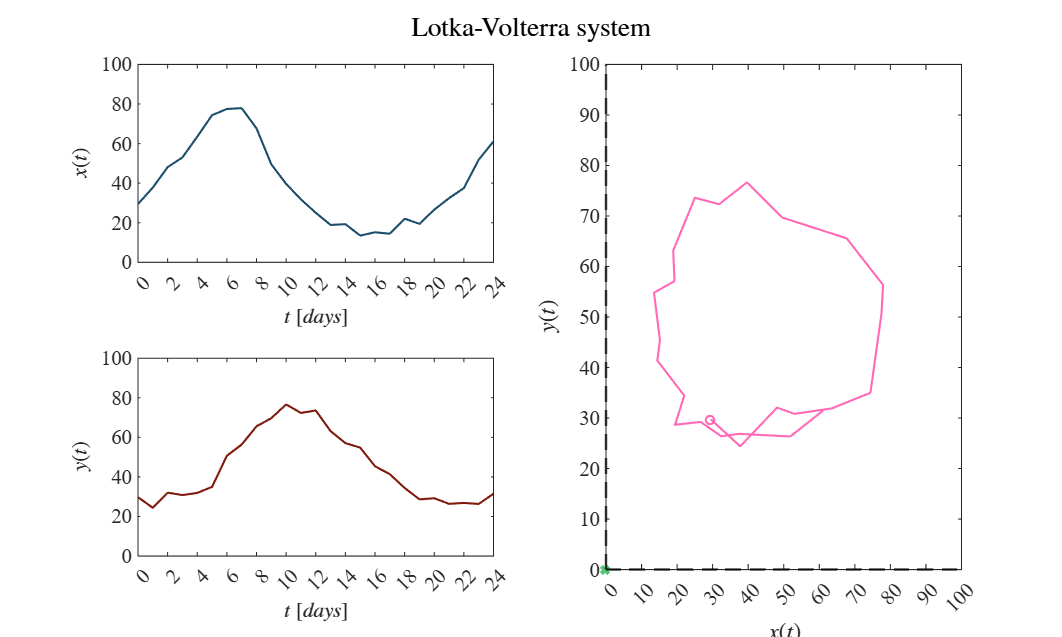

sys = readmatrix('dataxy.csv');
to = sys(:,1); xo = sys(:,2); yo = sys(:,3);
 alpha = 0.5;      beta = 0.01;
 delta = 0.001;    gamma = 0.2;
P=[alpha,beta,delta,gamma];
plotEDOsfit(to,xo,yo,P,0); 
ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'data fitting Lotka-Volterra.pdf', 'ContentType', 'Vector')

#### Smooth data

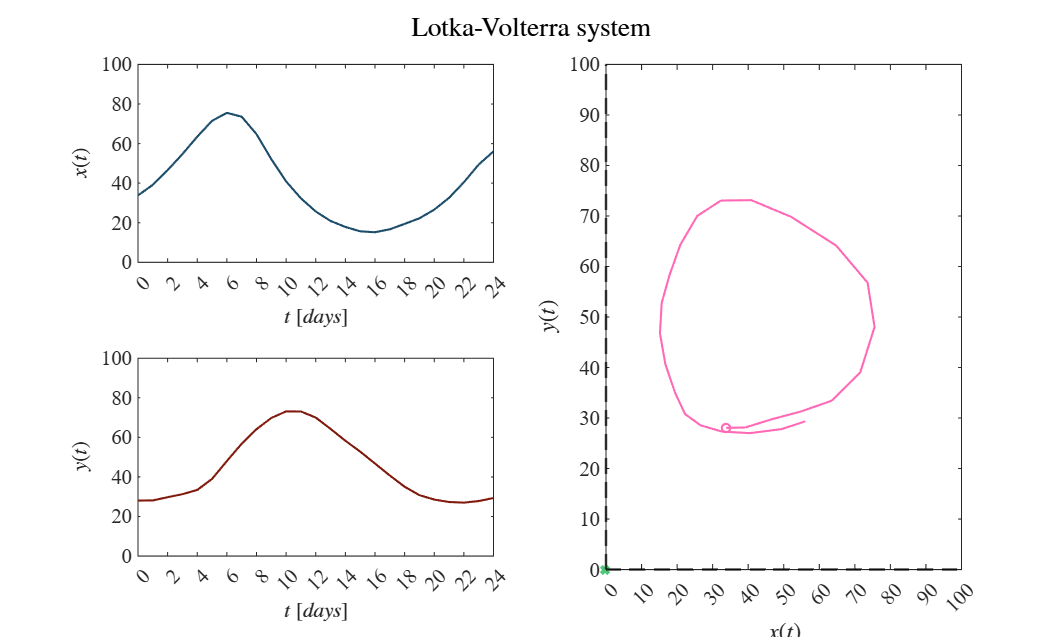

xo = smoothdata(xo,'gaussian',5);
yo = smoothdata(yo,'gaussian',5);
plotEDOsfit(to,xo,yo,P,0);
ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'Data fitting Lotka-Volterra (smooth).pdf','ContentType','Vector')

#### Fit data

P0 = [1;0.01;0.01;0.1];
mdl = variant(to,xo,yo,P0);


Sample size (n): 25
Parameters to be estimated (pars): 4
Degrees of freedom: 46
Significance level (alpha): 0.5
t-Student value:0.67986
Adjusted R-squared:0.99295
Corrected AIC (n/pars < 40):    Parameters    Estimate         SE           MoE                 CI95               pvalue  
    __________    _________    __________    __________    ______________________    __________

      alpha         0.42878     0.0070988     0.0048262      0.42396      0.43361    1.8226e-45
       beta       0.0090705    0.00017795    0.00012098    0.0089496    0.0091915    4.0067e-42
      delta       0.0053607    0.00010377    7.0547e-05    0.0052901    0.0054312     2.183e-42
      gamma         0.21696     0.0043147     0.0029334      0.21403      0.21989    7.4083e-42



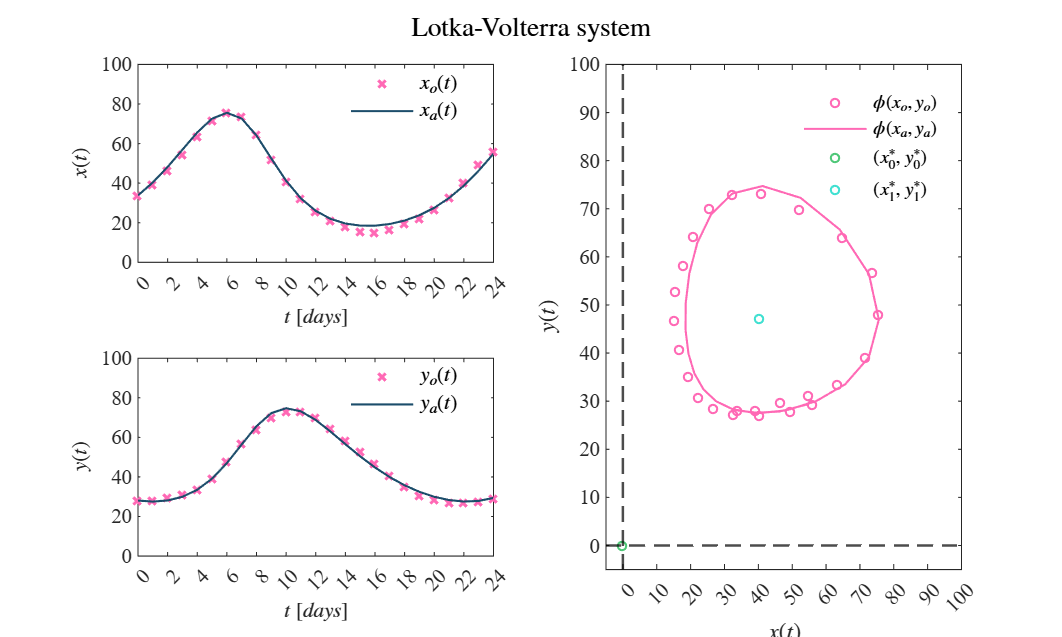

fa = mdl.Fitted;
fx = reshape(fa,[],2);
xa = fx(:,1); ya = fx(:,2);
P= table2array(mdl.Coefficients(:,1));
plotResults(to,[xo,xa],[yo,ya],P);
ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'Data fitting Lotka-Volterra (fitted).pdf','ContentType','Vector')

### Experimental data *k. marxianus*

#### Data fitting

clc; clear; close all

#### Raw data

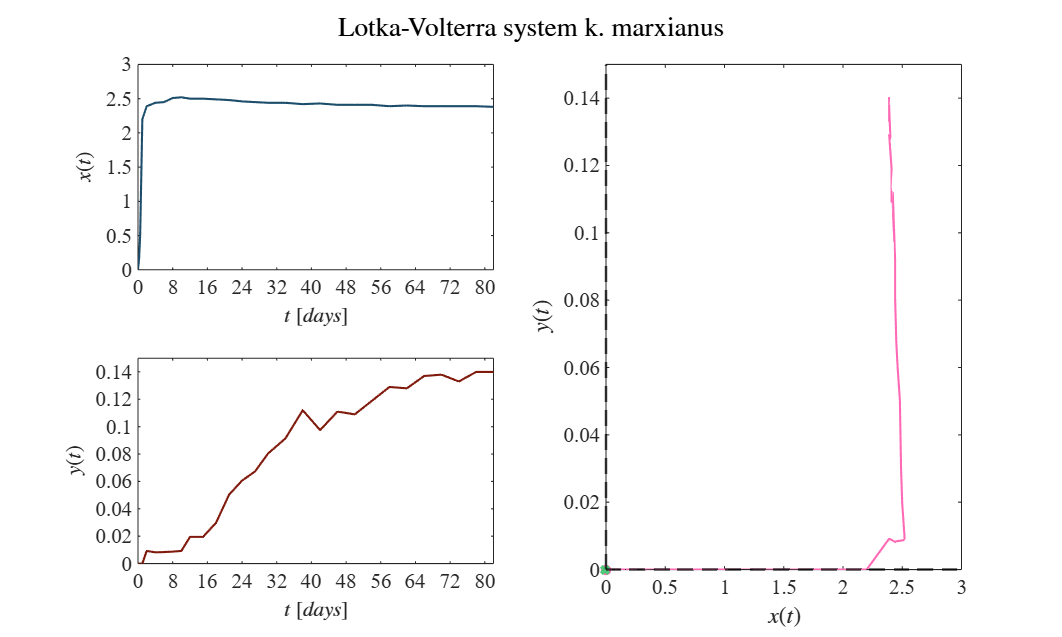

sys = readmatrix('Kmarxianus.csv');
to = sys(:,1); xo = sys(:,2); yo = sys(:,3);
 alpha = 0.5;      beta = 0.01;
 delta = 0.001;    gamma = 0.2;
P=[alpha,beta,delta,gamma];
plotEDOsKmarxianus(to,xo,yo,P,0); 
ttl = 'Lotka-Volterra system k. marxianus'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'Data k. marxianus Lotka-Volterra.pdf', 'ContentType', 'Vector')

#### Smooth data

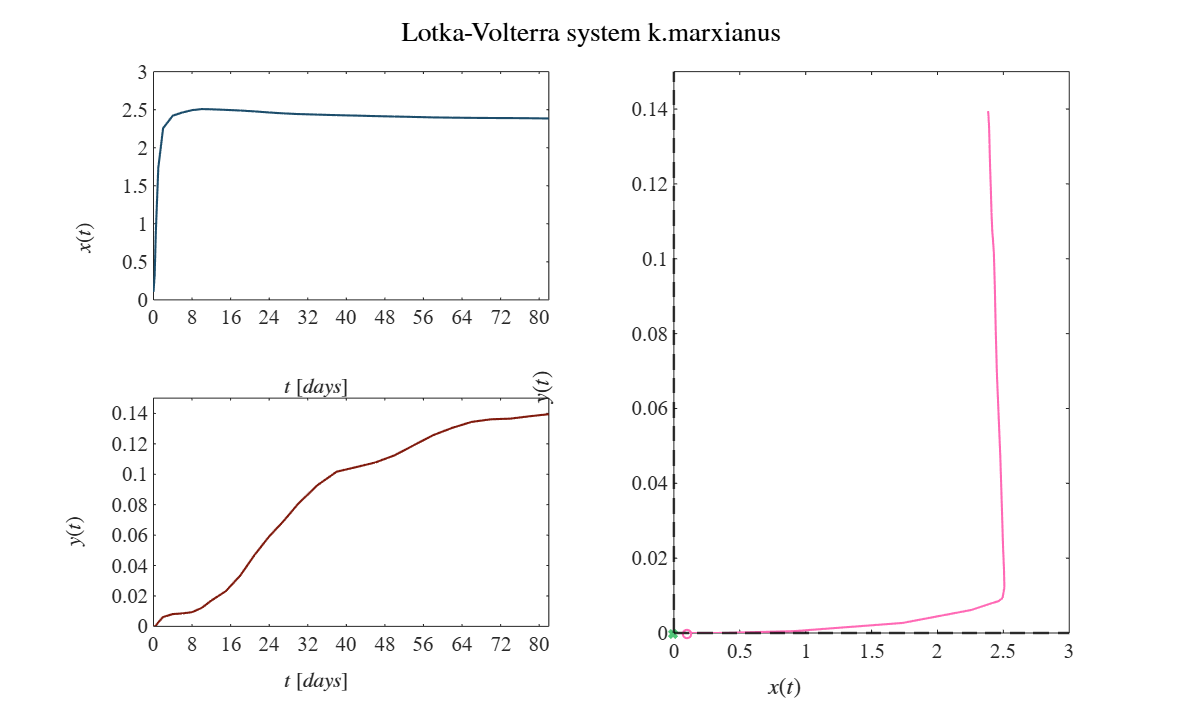

xo = smoothdata(xo,'gaussian',5);
yo = smoothdata(yo,'gaussian',5);
plotEDOsKmarxianus(to,xo,yo,P,0);
ttl = 'Lotka-Volterra system k.marxianus'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'Data k. marxianus Lotka-Volterra (smooth).pdf','ContentType','Vector')

#### Fit data

P0 = [1;0.01;0.01;0.1];
mdl_km = variable(to,xo,yo,P0);


Sample size (n): 29
Parameters to be estimated (pars): 4
Degrees of freedom: 57
Significance level (alpha): 0.05
t-Student value:2.0025
Adjusted R-squared:-0.12109
Corrected AIC (n/pars < 40):195.799

    Parameters    Estimate       SE           MoE               CI95              pvalue  
    __________    ________    _________    _________    ____________________    __________

      alpha       0.044336    0.0024244    0.0048548    0.039481    0.049191    1.6095e-25
       beta           0.01            0            0         NaN         NaN             0
      delta           0.01            0            0         NaN         NaN             0
      gamma            0.1            0            0         NaN         NaN             0



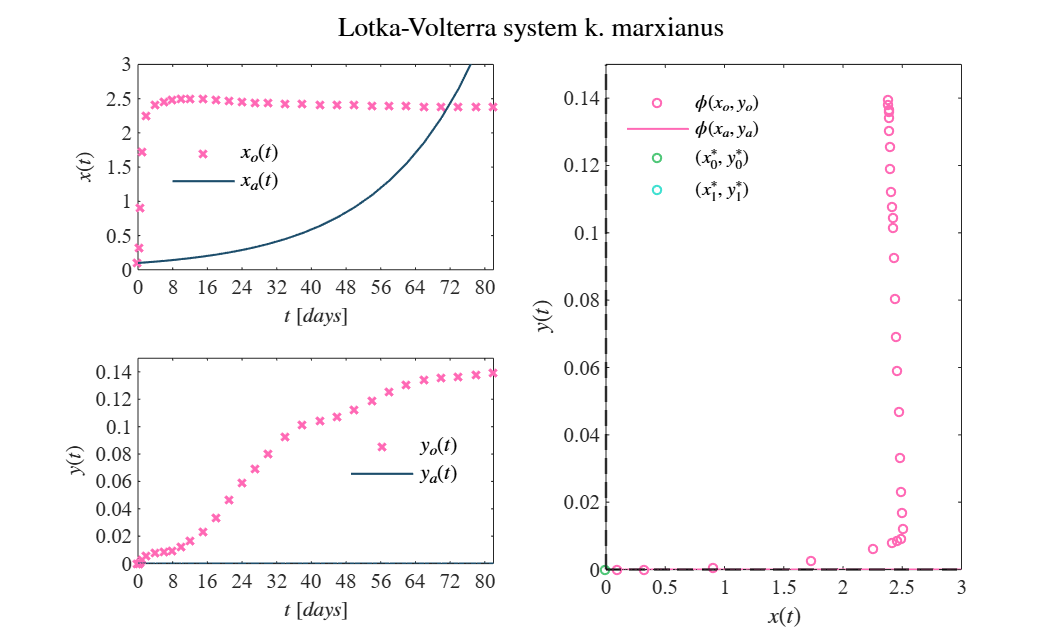

fa = mdl_km.Fitted;
fx = reshape(fa,[],2);
xa = fx(:,1); ya = fx(:,2);
P= table2array(mdl_km.Coefficients(:,1));
plotResultskm(to,[xo,xa],[yo,ya],P);
ttl = 'Lotka-Volterra system k. marxianus'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'Data k. marxianus Lotka-Volterra (fitted).pdf','ContentType','Vector')

### Functions

#### Euler's method

function [t,x,y] = sys_Euler (x0,y0,dt,tend,P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend/dt);
    t = (0:dt:tend)';
    x = zeros (length(t),1); x(1) = x0; 
    y = zeros (length(t),1); y(1) = y0;
    for i= 1:n
    x(i+1) = x(i) + (alpha*x(i) - beta*x(i)*y(i))*dt;
    y(i+1) = y(i) + (delta*x(i)*y(i) - gamma*y(i))*dt;
    end
end

#### Heun's method

function [t,x,y] = sys_Heun(x0,y0,dt,tend,P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend/dt);
    t = (0:dt:tend)';
    x = zeros (length(t),1); x(1) = x0; 
    y = zeros (length(t),1); y(1) = y0;
     
    for i=1:n
        [fx,fy]=f(x(i), y(i));
        xn= x(i) + fx*dt;
        yn= y(i) + fy*dt; %% diferencias finitas para resolver sistema de ecuaciones
        [fxn,fyn]=f(xn, yn);

        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
    end
    
    function [dx,dy]=f(x,y)
        dx = alpha*x - beta*x*y;
        dy = delta*x*y - gamma*y;
    end

end


#### Nonlinear regression algorithm

function mdl = variant(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];

    function fi = model(p,t)
        alpha = p(1); beta = p(2); delta = p(3); gamma = p(4);
        dt = 1E-1;
        t = reshape(t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = x0;
        y = zeros(length(time),1); y(1) = y0;
        
        for i = 1:n
        [fx,fy] = f(x(i), y(i));
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt; 
        [fxn,fyn] = f(xn, yn);
    
        x(i+1) = x(i) + (fx+fxn)*dt/2;
        y(i+1) = y(i) + (fy+fyn)*dt/2;
        end

        function [dx,dy]=f(x,y)
            dx= alpha*x - beta*x*y;
            dy = delta*x*y - gamma*y;
        end

        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        for j = 1:length(t)
            k = abs(time - t(j)) < 1E-9;
            xi(j)= x(k);
            yi(j)= y(k);
        end
        fi = [xi;yi];
    end
       mdl = fitnlm(to,fo,@model,P0);

       Estimate = table2array(mdl.Coefficients(:,1));
       SE = table2array(mdl.Coefficients(:,2));
       pvalue = table2array(mdl.Coefficients(:,4));
       alpha = 0.28;
       CI95 = coefCI(mdl,alpha);
       dof = mdl.DFE;
       tval = tinv(1 - alpha/2,dof);
       MoE = SE*tval;
       Parameters = ['alpha'; ' beta'; 'delta'; 'gamma'];
       Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

       fprintf(['\nSample size (n): ', num2str(numel(xo))])
       fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
       fprintf(['\nDegrees of freedom: ', num2str(dof)])
       fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
       fprintf(['\nt-Student value:', num2str(tval)])
       fprintf(['\nAdjusted R-squared:', num2str(mdl.Rsquared.Adjusted)])
       fprintf(['\nCorrected AIC (n/pars < 40):'], num2str(mdl.ModelCriterion.AIC), '\n\n')
       disp(Results)
end

#### Nonlinear regression algorithm *K. marxianus*

function mdlkm = variable(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1);
    to = [to; to];
    fo = [xo; yo];

    function fi = model(p,t)
        alpha = p(1); beta = p(2); delta = p(3); gamma = p(4);
        dt = 1E-2;
        t = reshape(t, [], 2); t = t(:,1);
        time = (0:dt:max(t))';
        n = length(time);
        x = zeros(n,1); x(1) = x0;
        y = zeros(n,1); y(1) = y0;
        
        for i = 1:n-1
            [k1x, k1y] = f(x(i), y(i));
            [k2x, k2y] = f(x(i) + k1x*dt/2, y(i) + k1y*dt/2);
            [k3x, k3y] = f(x(i) + k2x*dt/2, y(i) + k2y*dt/2);
            [k4x, k4y] = f(x(i) + k3x*dt, y(i) + k3y*dt);
            
            x(i+1) = x(i) + dt*(k1x + 2*k2x + 2*k3x + k4x)/6;
            y(i+1) = y(i) + dt*(k1y + 2*k2y + 2*k3y + k4y)/6;
        end
        
        function [dx, dy] = f(x, y)
            dx = alpha*x - beta*x*y;
            dy = delta*x*y - gamma*y;
        end
        
        xi = interp1(time, x, t, 'linear', 'extrap');
        yi = interp1(time, y, t, 'linear', 'extrap');
        fi = [xi; yi];
    end

    mdlkm = fitnlm(to, fo, @model, P0);

    Estimate = table2array(mdlkm.Coefficients(:,1));
    SE = table2array(mdlkm.Coefficients(:,2));
    pvalue = table2array(mdlkm.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdlkm, alpha);
    dof = mdlkm.DFE;
    tval = tinv(1 - alpha/2, dof);
    MoE = SE * tval;
    Parameters = ['alpha'; ' beta'; 'delta'; 'gamma'];
    resultskm = table(Parameters, Estimate, SE, MoE, CI95, pvalue);

    fprintf(['\nSample size (n): ', num2str(numel(xo))])
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value:', num2str(tval)])
    fprintf(['\nAdjusted R-squared:', num2str(mdlkm.Rsquared.Adjusted)])
    fprintf(['\nCorrected AIC (n/pars < 40):', num2str(mdlkm.ModelCriterion.AIC), '\n\n'])
    disp(resultskm)
end




### Solution by Heun's method

%dt = [2,1,0.5,0.25,1E-1,1E-2,1E-3,1E-4];
dt = 1E-1;
tend=100;
for i = 1:numel(dt)
    [t,x,y] = sys_Heun(x0,y0,dt(i),tend,P);
    plotEDOs(t,x,y,P,dt(i))
    exportgraphics(gcf,['Lotka-Volterra Heun',num2str(dt(i)),'.pdf'], 'ContentType', 'Vector')

end

Unrecognized function or variable 'x0'.

### Solutions and trajectories 

function  plotEDOs(t,x,y,P,dt)
set(figure(), 'Color' , 'w')
set(gcf, 'Units', 'Centimeters', 'Position', [2,2,20,12])
alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot (2,2,1)
    set (gca, 'FontName' , 'Times New Roman'); fontsize(10, 'points') 
    hold on; box on; grid off
    plot(t,x,' -', 'LineWidth',1, 'Color', [0.11,0.30,0.42])
    xlabel('$t$ $[days]$', 'Interpreter', 'Latex' )
    ylabel('$x(t)$', 'Interpreter', 'Latex' )
    xlim([0 100]); xticks(0:10:100)
    ylim([0 600]); yticks(0:100:600)
    
    subplot (2,2,3)
    set (gca, 'FontName', 'Times New Roman'); fontsize(10, 'points') 
    hold on; box on; grid off 
    plot (t,y,' -', 'LineWidth',1, 'Color', [0.50,0.10,0.05])
    xlabel('$t$ $[days]$', 'Interpreter', 'Latex')
    ylabel( '$y(t)$', 'Interpreter', 'Latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 100]); yticks(0:20:100)
    
    subplot (2, 2, [2 4]) 
    set (gca, 'FontName', 'Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off 
    plot (x,y,'-', 'LineWidth',1,'Color', [0,0.4470,0.7410])
    plot (x(1),y(1),'o','MarkerSize',4,'LineWidth',1, 'Color', [0,0.4470,0.7410])
    plot (0,0,'x','MarkerSize',5, 'LineWidth',1.5, 'Color', [0.25,0.88,0.82])
    plot (gamma/delta,alpha/beta,'x','MarkerSize',5,'LineWidth',1.5,'Color', [0.6350, 0.0780, 0.1840])
    xlabel('$x(t)$', 'Interpreter', 'Latex')
    ylabel('$y(t)$', 'Interpreter', 'Latex')
    xlim([-60 600]); xticks(0:100:600)
    ylim([-5 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    L= legend('$\phi(x,y)$','$(x(0),y(0))$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
    set(L,'Interpreter','Latex','Location', 'none', 'Position',[0.7548 0.1561 0.1474, 0.1705],'Box','Off')

    if dt == 0
        ttl = 'Lotka-Volterra system';
        sgtitle(ttl, 'Interpreter','latex')
    else
    ttl = ['Step size [dt]: ', num2str(dt)];
    sgtitle(ttl, 'Interpreter','latex')

    end
end

### Solution Data fitting

function plotEDOsfit(to,xo,yo,P,dt)
set(figure(), 'Color' , 'w')
set(gcf, 'Units', 'Centimeters', 'Position', [2,2,20,12])
alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot (2,2,1)
    set (gca, 'FontName' , 'Times New Roman'); fontsize(10, 'points') 
    hold on; box on; grid off
    plot(to,xo,' -', 'LineWidth',1, 'Color', [0.11,0.30,0.42])
    xlabel('$t$ $[days]$', 'Interpreter', 'Latex' )
    ylabel('$x(t)$', 'Interpreter', 'Latex' )
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)
    
    subplot (2,2,3)
    set (gca, 'FontName', 'Times New Roman'); fontsize(10, 'points') 
    hold on; box on; grid off 
    plot (to,yo,' -', 'LineWidth',1, 'Color', [0.50,0.10,0.05])
    xlabel('$t$ $[days]$', 'Interpreter', 'Latex')
    ylabel( '$y(t)$', 'Interpreter', 'Latex')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

    subplot (2, 2, [2 4]) 
    set (gca, 'FontName', 'Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off 
    plot (xo,yo,'-', 'LineWidth',1,'Color', [1, 0.41, 0.71])
    plot (xo(1),yo(1),'o','MarkerSize',4,'LineWidth',1, 'Color', [1, 0.41, 0.71])
    plot (0,0,'x','MarkerSize',5, 'LineWidth',2, 'Color', [0.31, 0.78, 0.47])
    plot (gamma/delta,alpha/beta,'x','MarkerSize',5,'LineWidth',1.5,'Color', [0.25, 0.88, 0.82])
    xlabel('$x(t)$', 'Interpreter', 'Latex')
    ylabel('$y(t)$', 'Interpreter', 'Latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1.2,'Color','k')
    yline(0,'--','LineWidth',1.2,'Color','k')
end

function plotResults(t,x,y,P)
set(figure(), 'Color' , 'w')
set(gcf, 'Units', 'Centimeters', 'Position', [2,2,20,12])
alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot (2,2,1)
    set (gca, 'FontName' , 'Times New Roman'); fontsize(10, 'points') 
    hold on; box on; grid off
    plot (t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5, 'Color', [1, 0.41, 0.71])
    plot(t,x(:,2),' -', 'LineWidth',1, 'Color', [0.11,0.30,0.42])
    xlabel('$t$ $[days]$', 'Interpreter', 'Latex' )
    ylabel('$x(t)$', 'Interpreter', 'Latex' )
    L= legend('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','off')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)
    
    subplot (2,2,3)
    set (gca, 'FontName' , 'Times New Roman'); fontsize(10, 'points') 
    hold on; box on; grid off
    plot (t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5, 'Color', [1, 0.41, 0.71])
    plot(t,y(:,2),' -', 'LineWidth',1, 'Color', [0.11,0.30,0.42])
    xlabel('$t$ $[days]$', 'Interpreter', 'Latex' )
    ylabel('$y(t)$', 'Interpreter', 'Latex' )
    L= legend('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','off')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

    subplot (2, 2, [2 4]) 
    set (gca, 'FontName', 'Times New Roman'); fontsize(10, 'points')
    hold on; box on; grid off 
    plot (x(:,1),y(:,1),'o','MarkerSize',4,'LineWidth',1, 'Color', [1, 0.41, 0.71])
    plot (x(:,2),y(:,2),'-', 'LineWidth',1,'Color', [1, 0.41, 0.71])
    plot (0,0,'o','MarkerSize',4, 'LineWidth',1, 'Color', [0.31, 0.78, 0.47])
    plot (gamma/delta,alpha/beta,'o','MarkerSize',4,'LineWidth',1,'Color', [0.25, 0.88, 0.82])
    xlabel('$x(t)$', 'Interpreter', 'Latex')
    ylabel('$y(t)$', 'Interpreter', 'Latex')
    xlim([-5 100]); xticks(0:10:100)
    ylim([-5 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1.2,'Color','k')
    yline(0,'--','LineWidth',1.2,'Color','k')
    L= legend('$\phi(x_o,y_o)$','$\phi(x_a,y_a)$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
    set(L,'Interpreter','Latex','Location', 'Best','Box','Off')

end

### Solution Data *K. marxianus*

function plotEDOsKmarxianus(to, xo, yo, P, dt)
    set(figure(), 'Color', 'w');
    set(gcf, 'Units', 'Centimeters', 'Position', [2, 2, 20, 12]);
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2, 2, 1);
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points');
    hold on; box on; grid off;
    plot(to, xo, '-', 'LineWidth', 1, 'Color', [0.11, 0.30, 0.42]);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$x(t)$', 'Interpreter', 'latex');
    xlim([0 82]); xticks(0:8:82);
    ylim([0 3]); yticks(0:0.5:3);

    subplot(2, 2, 3);
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points');
    hold on; box on; grid off;
    plot(to, yo, '-', 'LineWidth', 1, 'Color', [0.50, 0.10, 0.05]);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$y(t)$', 'Interpreter', 'latex');
    xlim([0 82]); xticks(0:8:82);
    ylim([0 0.15]); yticks(0:0.02:0.15);

    subplot(2, 2, [2, 4]);
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points');
    hold on; box on; grid off;
    plot(xo, yo, '-', 'LineWidth', 1, 'Color', [1, 0.41, 0.71]);
    plot(xo(1), yo(1), 'o', 'MarkerSize', 4, 'LineWidth', 1, 'Color', [1, 0.41, 0.71]);
    plot(0, 0, 'x', 'MarkerSize', 5, 'LineWidth', 2, 'Color', [0.31, 0.78, 0.47]);
    plot(gamma / delta, alpha / beta, 'x', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', [0.25, 0.88, 0.82]);
    xlabel('$x(t)$', 'Interpreter', 'latex');
    ylabel('$y(t)$', 'Interpreter', 'latex');
    xlim([0 3]); xticks(0:0.5:3);
    ylim([0 0.15]); yticks(0:0.02:0.15);
    xline(0, '--', 'LineWidth', 1.2, 'Color', 'k');
    yline(0, '--', 'LineWidth', 1.2, 'Color', 'k');
end
function plotResultskm(t, x, y, P)
    set(figure(), 'Color', 'w');
    set(gcf, 'Units', 'Centimeters', 'Position', [2, 2, 20, 12]);
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    subplot(2, 2, 1);
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points');
    hold on; box on; grid off;
    plot(t, x(:, 1), 'x', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', [1, 0.41, 0.71]);
    plot(t, x(:, 2), '-', 'LineWidth', 1, 'Color', [0.11, 0.30, 0.42]);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$x(t)$', 'Interpreter', 'latex');
    legend('$x_o(t)$', '$x_a(t)$', 'Interpreter', 'latex', 'Location', 'best', 'Box', 'off');
    xlim([0 82]); xticks(0:8:82);
    ylim([0 3]); yticks(0:0.5:3);

    subplot(2, 2, 3);
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points');
    hold on; box on; grid off;
    plot(t, y(:, 1), 'x', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', [1, 0.41, 0.71]);
    plot(t, y(:, 2), '-', 'LineWidth', 1, 'Color', [0.11, 0.30, 0.42]);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$y(t)$', 'Interpreter', 'latex');
    legend('$y_o(t)$', '$y_a(t)$', 'Interpreter', 'latex', 'Location', 'best', 'Box', 'off');
    xlim([0 82]); xticks(0:8:82);
    ylim([0 0.15]); yticks(0:0.02:0.15);

    subplot(2, 2, [2, 4]);
    set(gca, 'FontName', 'Times New Roman'); fontsize(10, 'points');
    hold on; box on; grid off;
    plot(x(:, 1), y(:, 1), 'o', 'MarkerSize', 4, 'LineWidth', 1, 'Color', [1, 0.41, 0.71]);
    plot(x(:, 2), y(:, 2), '-', 'LineWidth', 1, 'Color', [1, 0.41, 0.71]);
    plot(0, 0, 'o', 'MarkerSize', 4, 'LineWidth', 1, 'Color', [0.31, 0.78, 0.47]);
    plot(gamma / delta, alpha / beta, 'o', 'MarkerSize', 4, 'LineWidth', 1, 'Color', [0.25, 0.88, 0.82]);
    xlabel('$x(t)$', 'Interpreter', 'latex');
    ylabel('$y(t)$', 'Interpreter', 'latex');
    xlim([0 3]); xticks(0:0.5:3);
    ylim([0 0.15]); yticks(0:0.02:0.15);
    xline(0, '--', 'LineWidth', 1.2, 'Color', 'k');
    yline(0, '--', 'LineWidth', 1.2, 'Color', 'k');
    legend('$\phi(x_o, y_o)$', '$\phi(x_a, y_a)$', '$(x^*_0, y^*_0)$', '$(x^*_1, y^*_1)$', 'Interpreter', 'latex', 'Location', 'best', 'Box', 'off');
end
